## 任意一端主缆的悬链线方程

计算图示如下所示

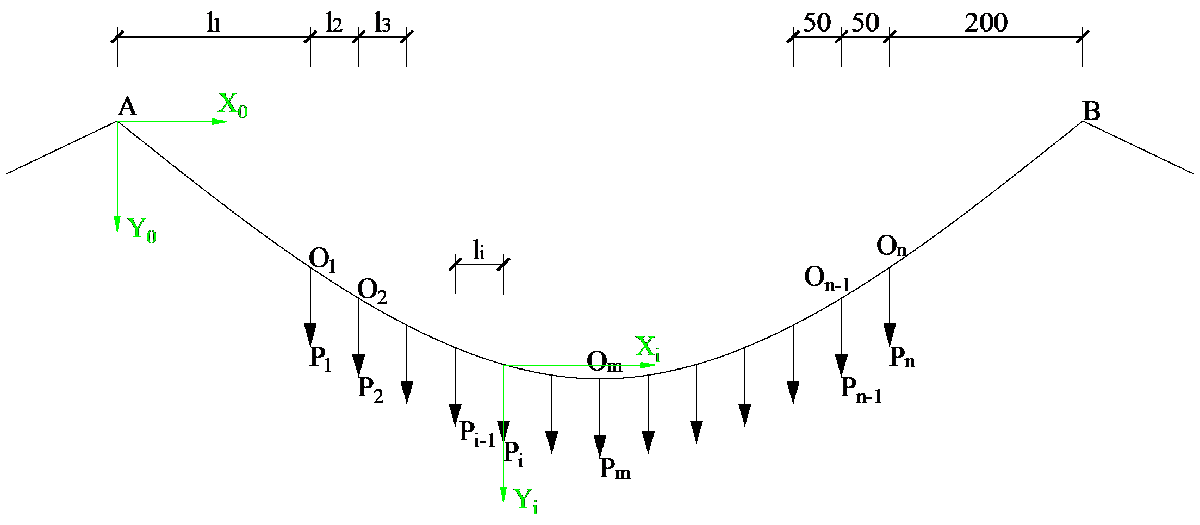

#### 已知条件：

- 塔顶A点、塔顶B点、主缆跨中点$O_m$三点坐标

- 各个吊索之间的水平间距$l_i$

#### 控制方程：

    以A点或者$O_i$点为原点，建立局部 $X_i -Y_i$坐标系如图中绿色箭头所示。$\tilde{O_i O_{i+1} }$段主缆的悬链线方程为：


$$y_i =c\left\lbrack \cosh \left(\frac{x_i }{c}+a_i \right)-{\cosh \;a}_i \right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


其中：

- $c=-\frac{H}{q}$不随主缆分段变化，$H\;$为主缆内力的水平分力，$H$为待求未知量，$q$为主缆自重荷载集度；

- $a_i$为第$i$段悬链线方程的待定参数，由于其表达形式复杂且于主缆线形本身密切相关，所以需要在之后的公式中进行迭代计算。

function [Xi,Yi] = Seg_catenary(q,n,Li,P,x)
    % 主缆自重q，单位kN/m
    % 吊杆数目n
    % Li为每个悬链线分段的水平长度组成的向量，length(Li) == n+1
    % 吊杆拉力P，P中每个元素表示第i根吊杆的拉力P_i，length(P) == n
    
    % 待求未知水平力H，单位kN
    % 待求未知参数a1
    
    H = x(1);
    % a1 = x(2);
    
    c = -H/q; 
    
    Xi = Li; % 因为xi为局部坐标系中的x坐标，因此，如果向量Xi是：在以O_i为原点建立的坐标系X_i-Y_i上，O_i+1的水平坐标xi所组成的向量...
            % ...那么向量Xi在数值上就等于Li
            % length(Xi) == n+1
           
    Yi = zeros([1,n+1]); % 初始化Yi向量，向量Y中的第i个元素是yi
                         % length(Yi) == n+1
                         % Yi中每个元素为每个分段悬链线的高差
    
    for i = 1:n+1
        xi = Xi(i);
        ai = Iter_ai(i,q,Li,P,x); % ai还需要通过迭代函数ITER_ai()进行求解
        yi = c*(cosh(xi/c+ai) - cosh(ai)); % 公式(1), 其中参数ai待定
        Yi(i) = yi;
    end

end